As MATLAB R2020b outputs values to 4 decimal places, the use of 'format long' allows the output values to display all digits. 

format long

**Part A: **By sourcing the data from the table and aranging them into an array, a linear plot of time vs velocity (t vs v) can be produced. Inside the plot script one can specify the title and axis labels. Line 5 'figure(1)' is designated as this script hold more than one figure thus requires seperation otherwise the figures with overwrite themselves.

t = [1.0 2.1 3.3 4.1 4.7 5.8 6.3 7.1 9.1 10.6 11.2 12.0]

t =    1.000000000000000   2.100000000000000   3.300000000000000   4.100000000000000   4.700000000000000   5.800000000000000   6.300000000000000   7.100000000000000   9.100000000000000  10.600000000000000  11.199999999999999  12.000000000000000


v = [26 28 29 29 30 30 29 28 27 27 26 26]

v =     26    28    29    29    30    30    29    28    27    27    26    26


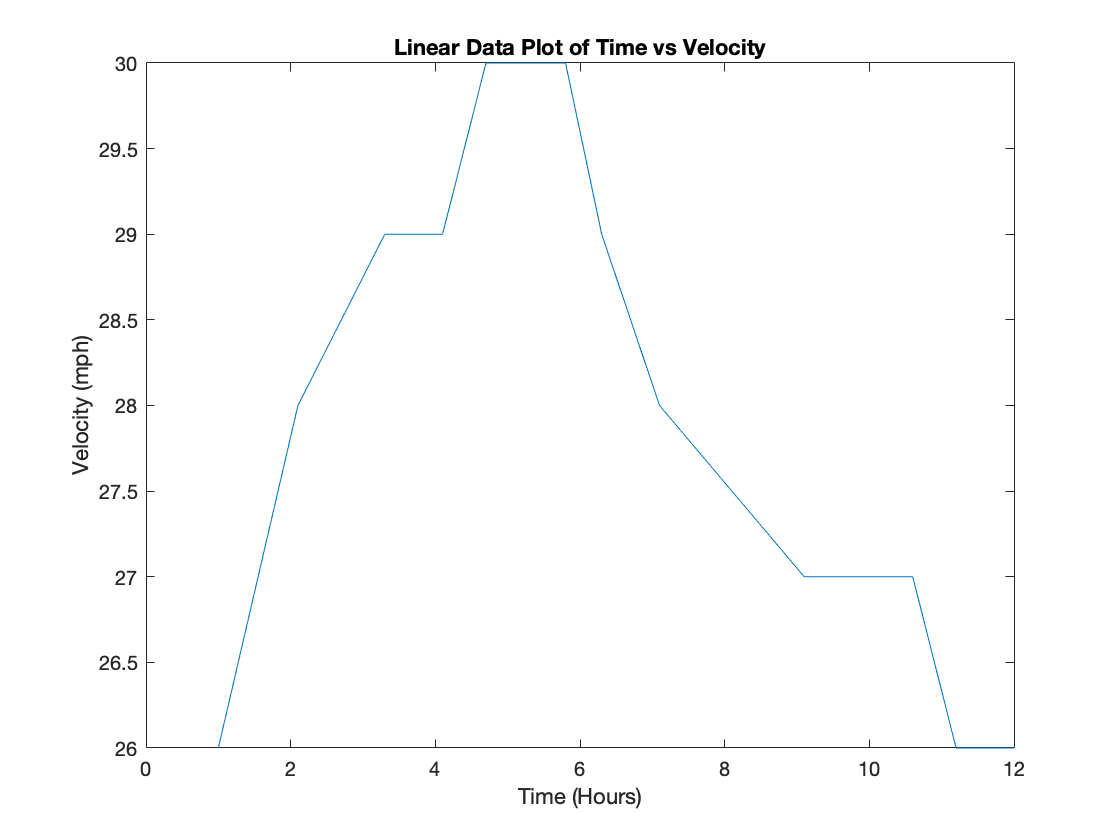


figure(1)
plot(t,v)
xlabel('Time (Hours)')
ylabel('Velocity (mph)')
title('Linear Data Plot of Time vs Velocity')

**Part B: **Utilising the 'trapz' command one can use the trapezoidal rule when comapring data, the reason this rule is used is because the velocity was recorded at various times and therefore is not linear for a precise calculation for distance travelled.

DistanceMiles = trapz(t,v)

DistanceMiles =      3.075500000000000e+02


**Part C: **Using polyfit to interpolate the data for 11th order polynomial by selecting the data arrays (t,v) and the degree/ order of polynomial (,11). Then estimating the speed from the polyfit data one must selectingt he interpolated data (p,) and subject it to the range of values (1hr-12hr) and one can specify the data must be retreived at 02hr intervals. This can be seen on line 12 as the min and max ranges are selected with a parameter in the middle.

p = polyfit(t,v,11)

p = 	1.0e+02 *

   0.000000040778371  -0.000002705677547   0.000077702658229  -0.001263868757451   0.012782859543479  -0.082934443363312   0.342165653110664  -0.848372764164416   1.060954555745427  -0.161686006792359  -0.922321073776635   0.860600050692712


Speed = polyval(p,[1:0.2:12])

Speed =   25.999999999716366  23.966070931360342  23.801296086393016  24.710600766853517  26.062394661291144  27.413490055916625  28.499954235003031  29.208267804490461  29.537417829062612  29.559452051613036  29.383490861095069  29.126173220012468  28.889940919620599  28.749385096186607  28.745036046108403  28.883421485360444  29.141902307546317  29.476674736309157  29.832363006697570  30.151780145371134  30.384672183569464  30.494552694480504  30.463052699542622  30.291531867130068  30.000000000017614  29.623665875865143  29.207649700793439  28.800555225725113  28.447690766070750  28.184751082478314  28.032723804566956  27.994667596696111  28.054830731663749  28.180347601938720  28.325479776565345  28.438073636775428  28.467607869303386  28.373923950620579  28.135497377280373  27.755946259124990  27.267419747775946  26.729597860193273  26.223305926775808  25.838244056037873  25.655100738943041  25.723409501245740  26.037971211470946  26.518558248629212  26.999999996275562  27.2426844

**Part D: **To start the figure one must specify the construction of the 2nd figure, after which the plot can be written. Though in this segment of the script two sets of data must be put onto one figure. The use of 'hold on' and 'hold off' is used to retain the current figure made for the plot in line 14, essentially saying we would liek to use the same figure. Adding a legend to specify both data sets is crucial for visual identification. The useof the 'b' and 'r--' is to select the line colour and type, for 'b' means solid black line and 'r--' means red dotted line.

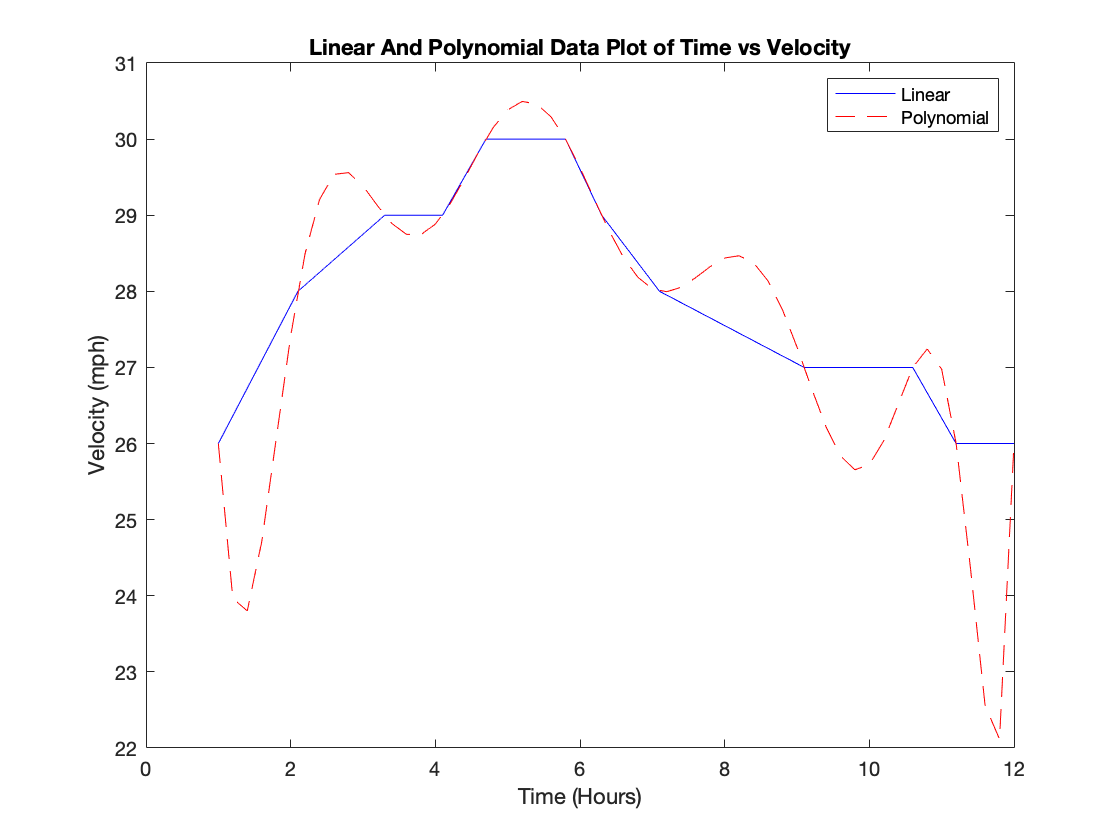

figure(2)
plot(t,v,'b')

hold on 
plot([1:0.2:12], Speed,'r--');
xlabel('Time (Hours)');
ylabel('Velocity (mph)');
title('Linear And Polynomial Data Plot of Time vs Velocity');
legend('Linear','Polynomial');
hold off

**Part E: **One could estimate the distance travelled by taking data from the graph by applying a polynomial trendline to obtain the average velocity per hour which will give the total miles travelled. Part C requests the use of an 11th degree/ order polynomial but howeve the output script produces a warning "*Warning: Polynomial is badly conditioned. Add points with distinct X values, reduce the degree of the polynomial, or try centering and scaling as described in HELP POLYFIT.*" this i because the starting value for the velocity is calculated lower in velocity than its linear counterpart.